syms t_c phi_25 MDD Cl MDD_eff phi_min M_crit M_cruise MDD_airfoil

Km = 1.05;

M_desired = 0.75;

ka = 0.87;

MDD_airfoil(Cl,t_c) = (Cl/10) + t_c - ka; 

MDD_eff = MDD * sqrt(cosd(phi_25));
t_c(MDD,Cl,phi_25) = 0.3*cosd(phi_25) * (( ((1 - ( (5+(MDD_eff^2)) / (5 + (Km-((0.25*Cl)^2)) ) )^(3.5)) * ((sqrt(1-(MDD_eff^2)))/(MDD_eff^2)) ))^(2/3));

simplify(t_c)

$$ans(MDD, Cl, phi\_25) = \frac{3\,\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)\,{\left(-\frac{\left({\left(-\frac{\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)\,{\mathrm{MDD}}^{2}+5}{\frac{{\mathrm{Cl}}^{2}}{16}-\frac{121}{20}}\right)}^{7/2}-1\right)\,\sqrt{1-{\mathrm{MDD}}^{2}\,\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)}}{{\mathrm{MDD}}^{2}\,\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)}\right)}^{2/3}}{10}$$



figure
hold on 
t_c_func(phi_25) = subs(t_c,[MDD,Cl],[M_desired,0])

$$t\_c\_func(phi\_25) = \frac{3\,\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)\,{\left(-\frac{16\,\left({\left(\frac{45\,\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)}{484}+\frac{100}{121}\right)}^{7/2}-1\right)\,\sqrt{1-\frac{9\,\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)}{16}}}{9\,\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)}\right)}^{2/3}}{10}$$

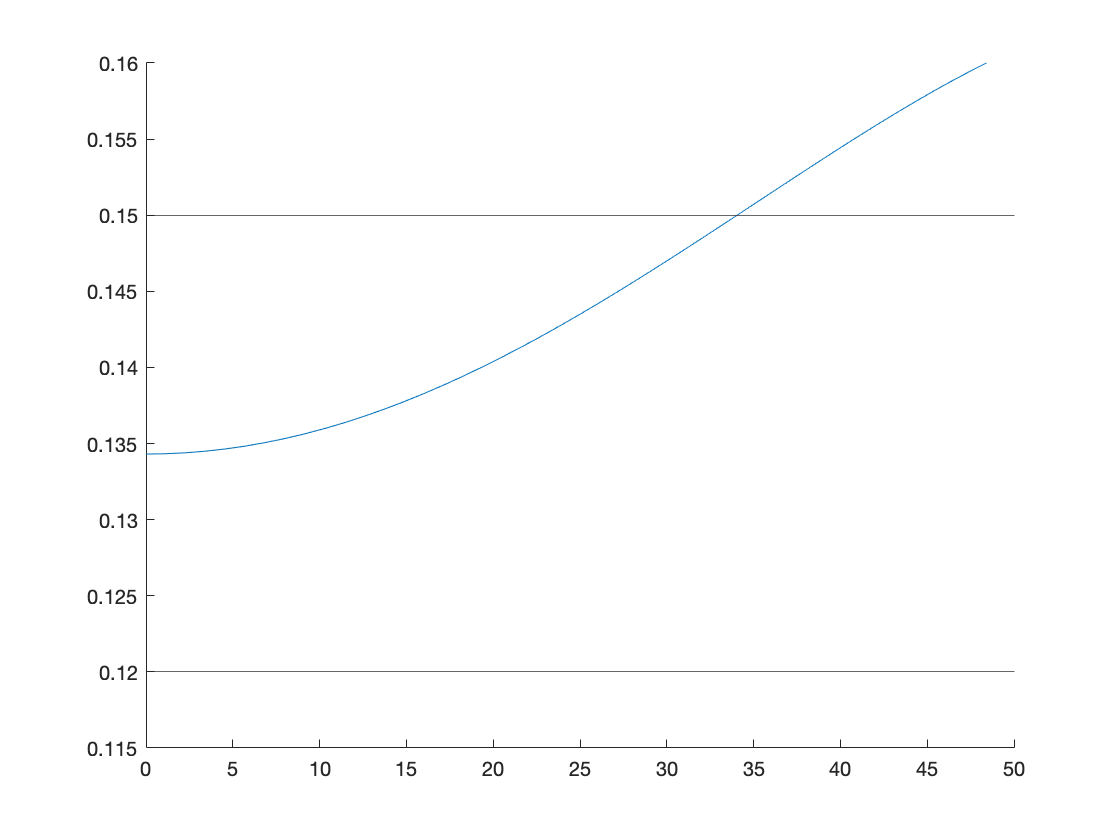


fplot(t_c_func,[0 50])



fsolve(@(x) double(t_c(M_desired,0,x)) - 0.15,20)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans = 34.1354